# Search Dropdown

This widget combines an edit field with a listbox that pops up beneath to mimic a search dropdown. While typing in the edit field, a filtered list of items shows up in the listbox. 

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 250 250]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);
gridObj.RowHeight = {'fit'};

Create and configure the widget:

sdWidget = wt.SearchDropDown(gridObj);
sdWidget.ValueChangedFcn = @(src,evt)disp(evt);


Then set the list of items to select from.  You may then type a substring in the field to show a filtered list to select from.

sdWidget.Items = ["Primary Current","Secondary Current","Primary Voltage","Secondary Voltage"];

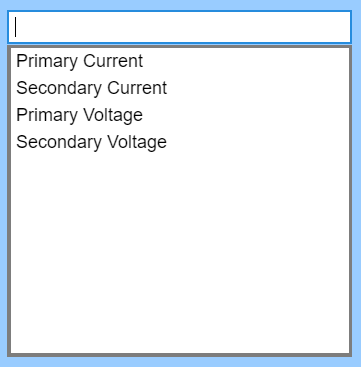  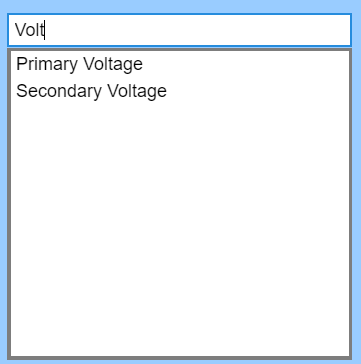

*Copyright 2025 The MathWorks, Inc.*